# Q1. When the x values are given as points

x = [0 1 2 3 4 5]

x =      0     1     2     3     4     5


y = [1.0 1.4 1.9 1.7 1.5 1.2]

y =     1.0000    1.4000    1.9000    1.7000    1.5000    1.2000


[hseries] = harmonic_analysis(x, y, 2);

Divided 2*pi into 6 intervals of 1.04720 each
Harmonic Series is : 


$$0.1732050808\,\sin\left(1.047197551\,t\right)-0.1\,\cos\left(2.094395102\,t\right)-0.3666666667\,\cos\left(1.047197551\,t\right)-0.05773502692\,\sin\left(2.094395102\,t\right)+1.45$$

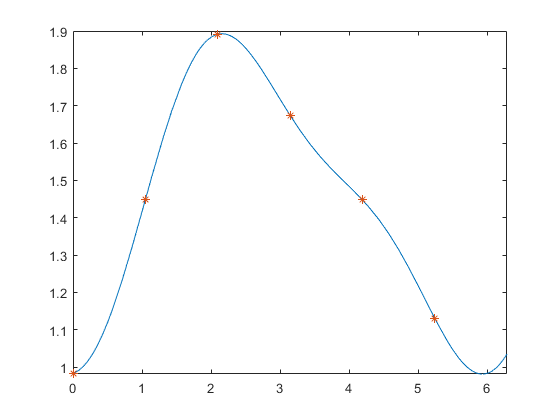

fplot(hseries, [0 2*pi])
hold on;
x = 0:(2*pi/6):(2*pi/6)*5; %% take care of the angles, we plot 
y = subs(hseries, x);
plot(x, y, '*')

hold off;

# Q2. When x is given in terms of angles

x = 0:pi/4:7*pi/4

x =          0    0.7854    1.5708    2.3562    3.1416    3.9270    4.7124    5.4978


y = [0.5 2.4 3.7 5.3 1 2.5 4.7 1.2]

y =     0.5000    2.4000    3.7000    5.3000    1.0000    2.5000    4.7000    1.2000


x = 0:(length(y)-1)

x =      0     1     2     3     4     5     6     7


[hseries] = harmonic_analysis(x, y, 3);

Divided 2*pi into 8 intervals of 0.78540 each
Harmonic Series is : 


$$0.6174621202\,\cos\left(2.35619449\,t\right)+0.9571067812\,\sin\left(2.35619449\,t\right)-0.8674621202\,\cos\left(0.7853981634\,t\right)-1.725\,\cos\left(1.570796327\,t\right)+0.4571067812\,\sin\left(0.7853981634\,t\right)-0.4\,\sin\left(1.570796327\,t\right)+2.6625$$

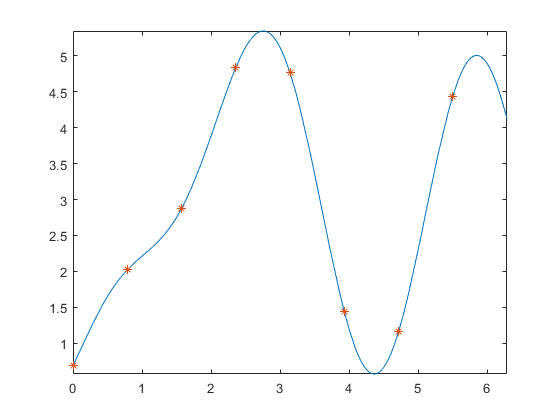

fplot(hseries, [0 2*pi])
hold on;
x = 0:(2*pi/8):7*(2*pi/8);  % here we divide 2*pi into 8 intervals, so 2*pi/8 each intervals, 
                            % the last interval is number of data points -1 * size of each interval
y = subs(hseries, x);
plot(x, y, '*')

hold off;